# **BS1 USRP N310 Transmitter **

clear;
close all;
% 第一部分可以认为是控制基站的功能
% The chosen set of OFDM parameters overall for all BSs:
overAllOfdmParams.online_BS               = 1;              % number of online data BS 
overAllOfdmParams.FFTLength               = 256;              % FFT length
overAllOfdmParams.CPLength                = ceil(overAllOfdmParams.FFTLength*0.25);   % Cyclic prefix length
overAllOfdmParams.PilotSubcarrierSpacing  = 36;                                 % Pilot sub-carrier spacing
total_RB                                  = 17;                                % User input Resource block number

% 调用calculateRBFinal函数确保最终的RB确定的子载波总数能够被pilot subcarrier spacing整除
[RB_verified, MaxRB] = calculateRBFinal(overAllOfdmParams, total_RB);
% 补充，其实新的算法不需要这个强限制，直接传入total RB即可
% check if RB_verified exceed MaxRB
if total_RB > MaxRB || RB_verified > MaxRB
    error('Error: Defined RB (%d) exceeds the system maximum allowed RB (%d). ', RB_verified, MaxRB);
end

overAllOfdmParams.total_RB                     = total_RB;
overAllOfdmParams.total_NumSubcarriers         = overAllOfdmParams.total_RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
overAllOfdmParams.guard_interval = (overAllOfdmParams.FFTLength - overAllOfdmParams.total_NumSubcarriers) / 2;     % Guard interval, 单侧的空载波
% check if NumSubcarriers less than FFTLength
if overAllOfdmParams.total_NumSubcarriers > overAllOfdmParams.FFTLength
    error('Total NumSubcarriers: (%d) exceeds Total FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        overAllOfdmParams.total_NumSubcarriers, overAllOfdmParams.FFTLength);
end


% 接下来是针对N310 BS1的radio resource OFDM parametr 设置
BS_id                             = 1;                    %当前基站的ID标识符
BWPoffset                         = 0;                    %当前基站的总带宽offset（单位/1个子载波），offset设置的是实际带宽start位置相对于初始计算的start的位置的偏移
% 根据BS id计算基站分配到的无线频谱资源, calculate allocated radio resource
[alloc_RadioResource, all_radioResource]     = calculateBWPs(overAllOfdmParams, BS_id, BWPoffset);

% 将部分total 全局参数和计算得到的分配给当前基站的空口资源赋给本地基站OFDMParam参数
OFDMParams.online_BS              = overAllOfdmParams.online_BS;                 % number of online data BS 
OFDMParams.BS_id                  = BS_id;                                       % BS id information
OFDMParams.BWPoffset              = BWPoffset;                                    %当前基站的总带宽offset（单位/1个子载波）
OFDMParams.FFTLength              = overAllOfdmParams.FFTLength;                  % FFT length
OFDMParams.CPLength               = overAllOfdmParams.CPLength;                   % Cyclic prefix length
OFDMParams.PilotSubcarrierSpacing = overAllOfdmParams.PilotSubcarrierSpacing;     % Pilot sub-carrier spacing这里直接默认为全局配置，后续可以针对化修改，即每个基站的pilot间隔不一样
OFDMParams.NumSubcarriers               = alloc_RadioResource.UsedSubcc;                 % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
OFDMParams.subcarrier_start_index       = alloc_RadioResource.subcarrier_start_index;    % 对应分配的BWP子载波起始位置
OFDMParams.subcarrier_end_index         = alloc_RadioResource.subcarrier_end_index;      % 对应分配的BWP子载波结束位置
OFDMParams.subcarrier_center_offset     = alloc_RadioResource.subcarrier_center_offset;  % 对应分配的BWP子载波中心偏移（相对于DC子载波)
OFDMParams.BWPoffset     = alloc_RadioResource.BWPoffset;                                % 对应分配的BWP人为设置Offset
OFDMParams.Subcarrierspacing      = 30e3;                          % Sub-carrier spacing of 30 KHz
OFDMParams.guard_interval         = overAllOfdmParams.guard_interval;              % 基站使用带宽的保护间隔
OFDMParams.channelBW              = (OFDMParams.guard_interval+OFDMParams.NumSubcarriers)*OFDMParams.Subcarrierspacing;   % Bandwidth of the channel for filter to pass
OFDMParams.signalBW               = (2*OFDMParams.guard_interval+OFDMParams.NumSubcarriers)*OFDMParams.Subcarrierspacing;   % Bandwidth of the signal for filter to cut-off


% Data Parameters
dataParams.modOrder       = 64;   % Data modulation order
dataParams.coderate       = "2/3";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame 20 for setup1
dataParams.numFrames      = 10000;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.printunderflow   = true;                    % Switch to enable or disable the print of underflow 
dataParams.verbosity      = true;                    % Switch to enable or disable the data diagnostic output

## Initialize Transmitter Parameters

radioDevice            = "N310";  % Choose the radio device for transmission
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
centerFrequency        = 2.2e9;
gain                   = 50;  % Set radio gain
gain                   = 45; % Set radio gain

[sysParam,txParam,trBlk] = helperOFDMSetParamsSDR(OFDMParams, dataParams, all_radioResource);
sysParam.total_usedSubcc = overAllOfdmParams.total_NumSubcarriers;
sysParam.total_usedRB = overAllOfdmParams.total_RB;
sampleRate               = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
ofdmTx                   = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain,channelmapping);

Checking radio connections...



% Get the radio transmitter and spectrum analyzer system object system object for the user to visualize the transmitted waveform.
[radio,spectrumAnalyze] = helperGetRadioTxObj(ofdmTx);
radio.TransportDataType = "int16";

## Generate Transmitter Waveform 

### **Transmit Frame Structure**

**Synchronization Symbol (SS)**

**Reference Symbol (RS)**

**Header Symbol**

**Pilot Signals**

**DC and Guard Subcarriers**

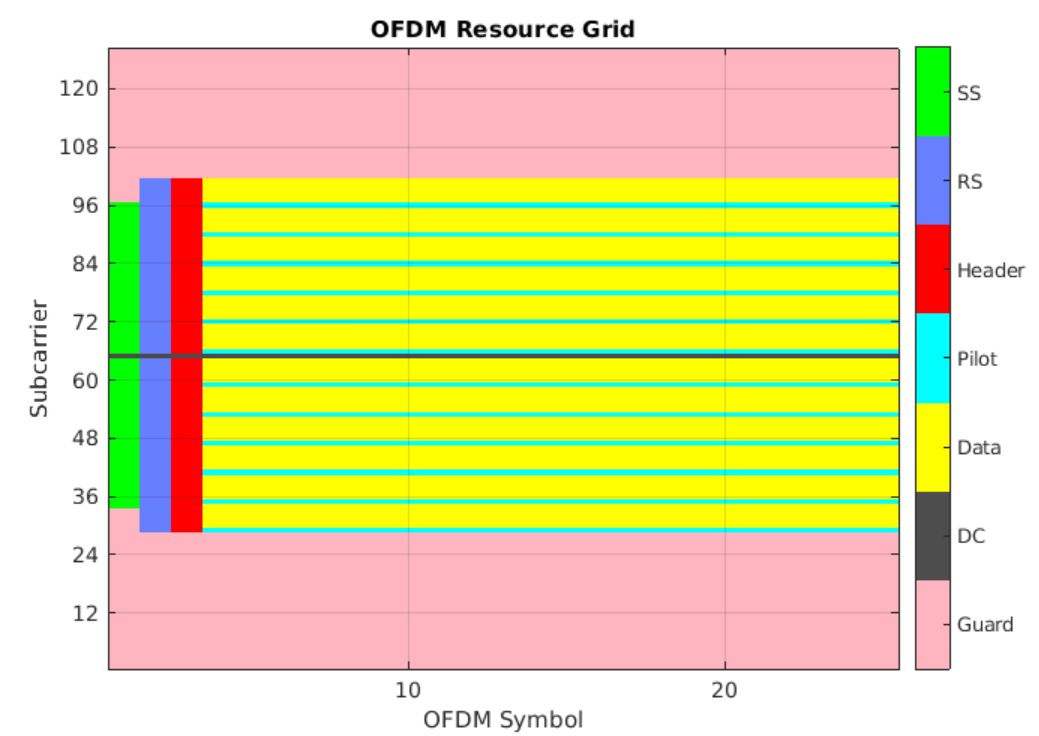

### Transmitter processing

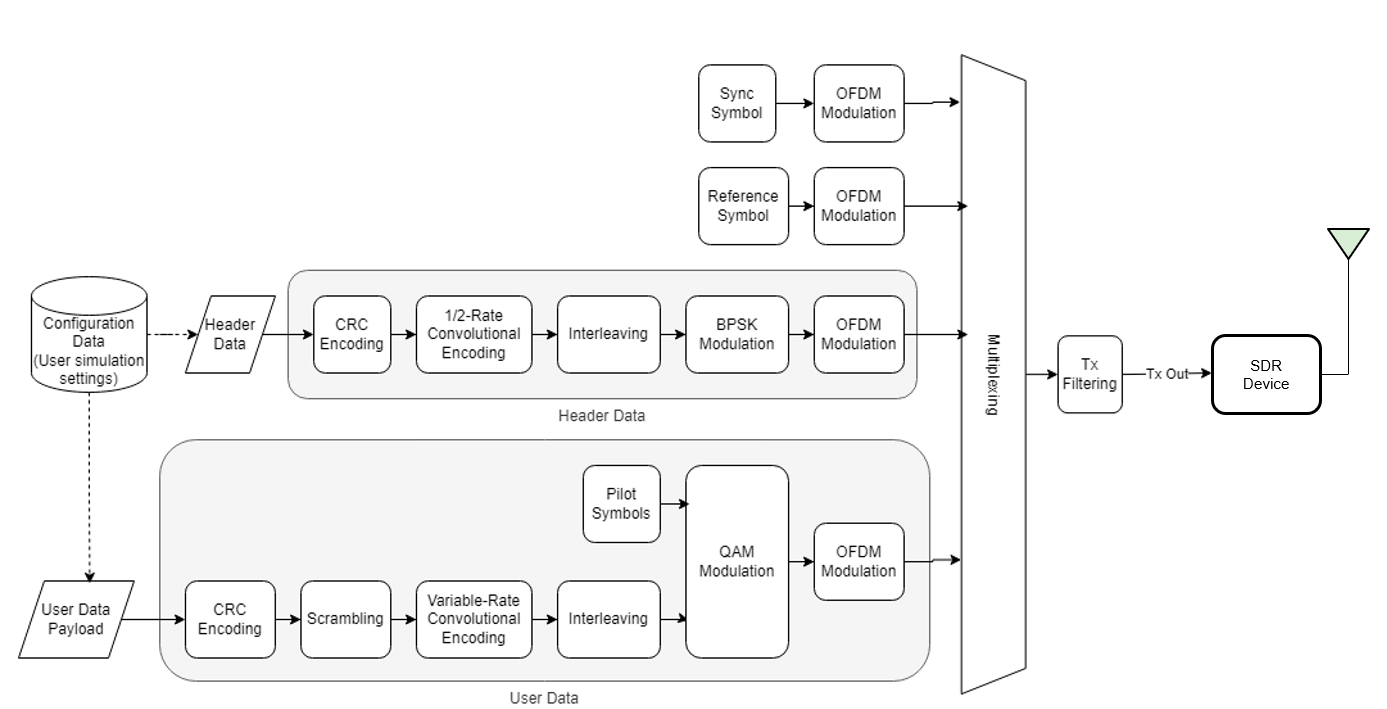

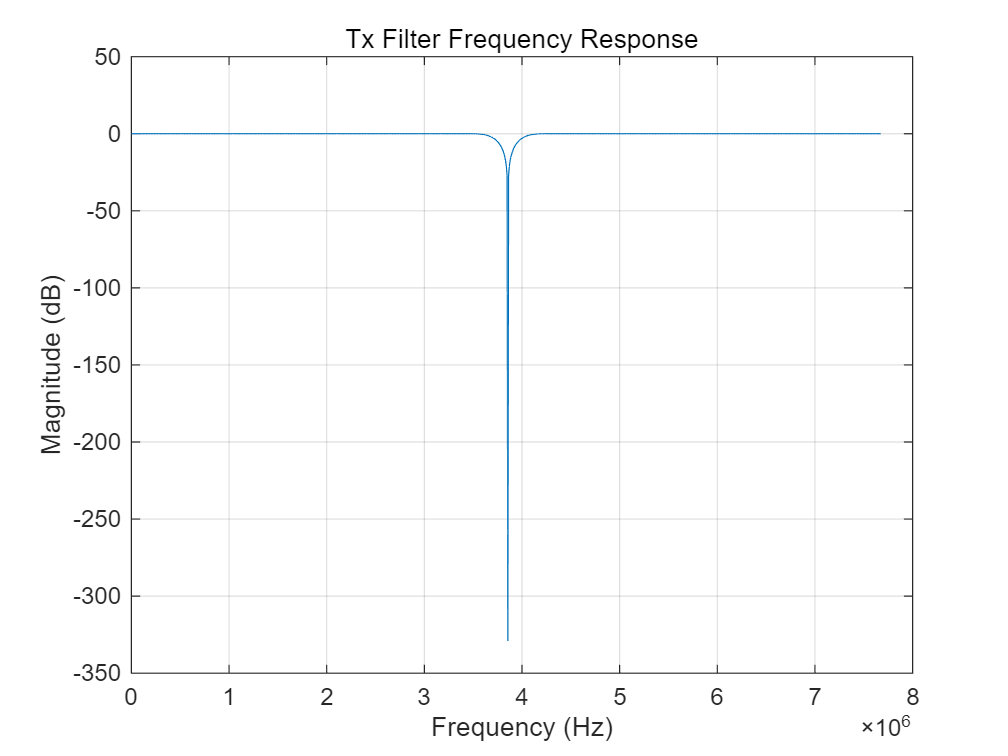


% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);

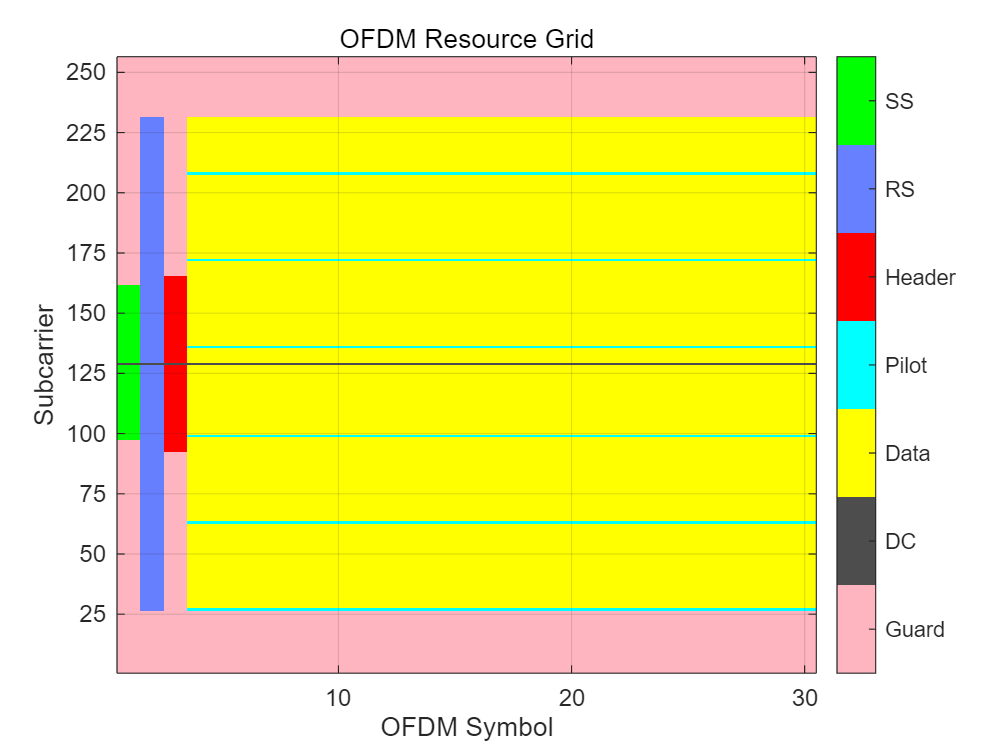

tunderrun = 0; % Initialize count for underruns

% A known payload is generated in the function helperOFDMSetParams with
% respect to the calculated trBlkSize
% Store data bits for BER calculations
txParam.txDataBits = trBlk;
[txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

% Display the grid if verbosity flag is enabled
if dataParams.verbosity
    helperOFDMPlotResourceGrid(txGrid,sysParam);
end

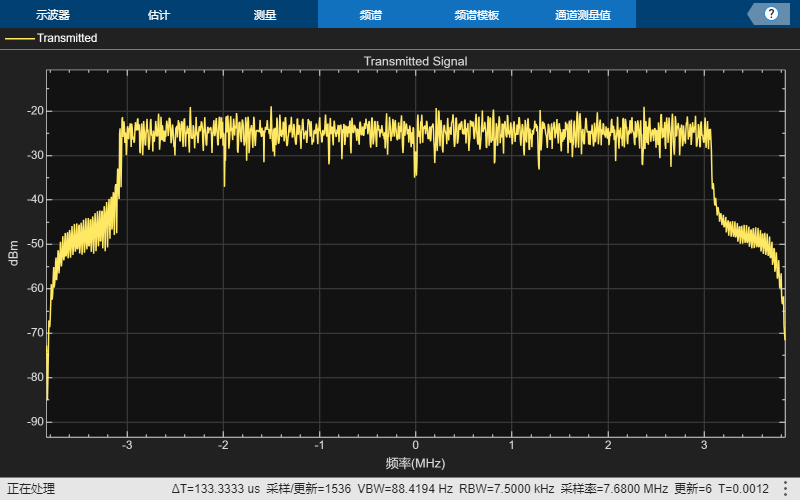


% Repeat the data in a buffer for PLUTO radio to make sure there are less
% underruns. The receiver decodes only one frame from where the first
% synchroization signal is received
txOutSize = length(txOut);
if contains(radioDevice,'PLUTO') && txOutSize < 48000
    frameCnt = ceil(48000/txOutSize);
    txWaveform = zeros(txOutSize*frameCnt,1);
    for i = 1:frameCnt
        txWaveform(txOutSize*(i-1)+1:i*txOutSize) = txOut;
    end
else
    txWaveform = txOut;
end

if dataParams.enableScopes
    spectrumAnalyze(txOut);
end

transmit_flag = 0;
txWaveform = [txWaveform];
% txWaveform = [txWaveform,txWaveform];
% txWaveform = [txWaveform,txWaveform,txWaveform,txWaveform];


## Transmit Over Radio

for frameNum = 1:sysParam.numFrames+1
    underrun = radio(txWaveform);
    tunderrun = tunderrun + underrun;  % Total underruns
    if transmit_flag == 0
        fprintf('-----------BS1 N310 starting transmitting at Rfq %s!----------------\n', mat2str(centerFrequency))
        fprintf('-----------TR antennal %s----------------\n', mat2str(channelmapping))
        fprintf('-----------Gain %s----------------', mat2str(gain))
        transmit_flag = 1;
    end
    if underrun > 0
        if dataParams.printunderflow
            fprintf('Underrun occurred at frame number: %d\n', frameNum);
    
        end
    end
end

-----------BS1 N310 starting transmitting at Rfq 2200000000!----------------


-----------TR antennal 1----------------


-----------Gain 45----------------

if transmit_flag == 1
    fprintf('----------BS1 N310 ending of transmitting at Rfq %s!-------------', mat2str(centerFrequency))
end

----------BS1 N310 ending of transmitting at Rfq 2200000000!-------------

% 输出总的underrun数目
fprintf('Total number of underruns: %d\n', tunderrun);

Total number of underruns: 0


% radio.CenterFrequency = 3.1e9;
% transmit_flag = 0;
% for frameNum = 1:sysParam.numFrames+1
%     underrun = radio(txWaveform);
%     tunderrun = tunderrun + underrun;  % Total underruns
%     if transmit_flag == 0
%         fprintf('-----------starting transmitting at frequency band 2!----------------')
%         transmit_flag = 1;
%     end
% end
% if transmit_flag == 1
%     fprintf('----------ending of transmitting at frequency band 2-------------')
% end

% Clean up the radio System object
release(radio);